# Lab Activity 5

### Carson Batchelor ###

## Item 2

% Write and Call key2note.m function
X=1

X = 1

keynum=55

keynum = 55

dur=.01

dur = 0.0100

fs=22050

fs = 22050


tone = key2note(X, keynum, dur, fs)

tone =     1.0000    0.9843    0.9378    0.8618    0.7589    0.6321    0.4855    0.3237    0.1517   -0.0250   -0.2009   -0.3706   -0.5286   -0.6700   -0.7905   -0.8861   -0.9540   -0.9919   -0.9987   -0.9743   -0.9192   -0.8354   -0.7253   -0.5925   -0.4412   -0.2760   -0.1021    0.0750    0.2497    0.4166    0.5704    0.7063    0.8201    0.9082    0.9678    0.9970    0.9950    0.9618    0.8984    0.8069    0.6900    0.5515    0.3957    0.2275    0.0522   -0.1247   -0.2978   -0.4615   -0.6108   -0.7408


tt = 0:(1/fs):0.01

tt =          0    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0010    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013    0.0013    0.0014    0.0014    0.0015    0.0015    0.0015    0.0016    0.0016    0.0017    0.0017    0.0018    0.0018    0.0019    0.0019    0.0020    0.0020    0.0020    0.0021    0.0021    0.0022    0.0022


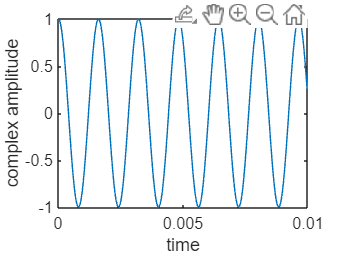

% Plot Function Output

plot(tt,tone)
xlabel("time")
ylabel("complex amplitude")

### You can take notes/add text here for yourself ###

## Item 3: play_scale_starter.m code

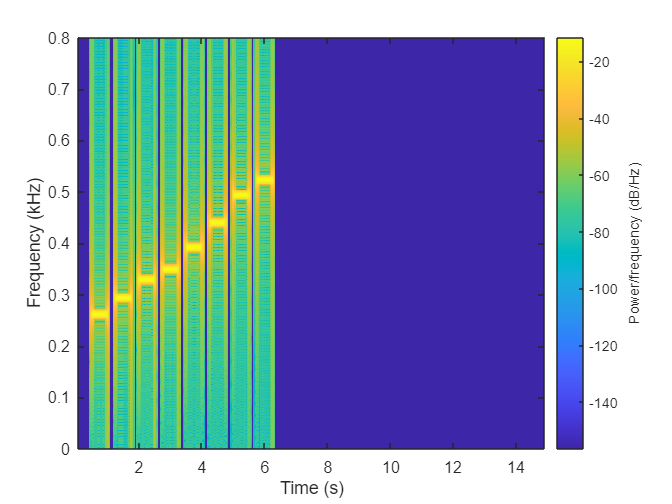

%--- play_scale.m
%---
scale.keys = [ 40 42 44 45 47 49 51 52 ];
%--- NOTES: C D E F G A B C
% key #40 is middle-C
%

fs = 22050;
beats_per_min = 60;

beats_per_sec = beats_per_min/60;
sec_per_beat = 1/beats_per_sec;
sec_per_pulse = sec_per_beat/4;

% duration of each note in scale
pulses_per_note = 2;
scale.durations(1:length(scale.keys)) = pulses_per_note*sec_per_pulse; % in seconds

% start times of each note in scale
scale.noteStart = [1:length(scale.keys)]*3; % start each note three pulses later

% allocate up to sixty pulses total
tt = 0:(1/fs):60*sec_per_pulse;
xx = zeros(1, length(tt));

for kk = 1:length(scale.keys)
    keynum = scale.keys(kk);
    
    % Complete the following line of code and uncomment to run
    tone = key2note(X, keynum, scale.durations(kk), fs); %<============= FILL IN THIS LINE
    
    note_indx_start = round((scale.noteStart(kk)-1)*sec_per_pulse*fs);
    note_indx_stop = note_indx_start+length(tone)-1;
    xx(note_indx_start:note_indx_stop) = xx(note_indx_start:note_indx_stop) + tone; %<=== Insert the note
end

spectrogram(xx,4096,3200,16384,fs,'yaxis')
ylim([0,0.8])

soundsc( xx, fs )